% initSim
s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


% L_f = l_f*Lbase1v

L_f = 6.3746e-08

% R_f = r_f*Zbase1v

R_f = 4.7610e-06

% C_f = 0.0757204*Cbase1v

C_f = 0.3189

% c_f = 0.0757

% plant
    
% G_plant = 1/(s*L_f)

G_plant =
 
       1
  -----------
  6.375e-08 s
 
Continuous-time transfer function.
Model Properties


% T_delay = 0.1e-3

T_delay = 1.0000e-04

% G_sensor = 1/(1+s*T_delay)

G_sensor =
 
       1
  ------------
  0.0001 s + 1
 
Continuous-time transfer function.
Model Properties


% G_i = G_plant*G_sensor

G_i =
 
               1
  ---------------------------
  6.375e-12 s^2 + 6.375e-08 s
 
Continuous-time transfer function.
Model Properties



% f_sw = 10000
f_c = 1/10*f_sw

f_c = 1000



Kp_cc = l_f*f_c%0.2 %50

Kp_cc = 26.5000

Ki_cc = r_f*f_c%5

Ki_cc = 6.3000

Ti_cc = 0.003

Ti_cc = 0.0030

% G_cc = Kp_cc +Ki_cc/s  

G_cc =
 
  26.5 s + 6.3
  ------------
       s
 
Continuous-time transfer function.
Model Properties


% % G_cc = Kp_cc*(1 + s*Ti_cc)/(s*Ti_cc)
% Kp_cc*(1+1/Ti_cc/s)

ans =
 
  26.5 s + 8833
  -------------
        s
 
Continuous-time transfer function.
Model Properties


% % r_f*f_c

ans = 6.3000

% % l_f*f_c

ans = 26.5000

% % Ki_cc = Kp_cc/Ti_cc

% Kp_cc+Ki_cc/s

ans =
 
  26.5 s + 6.3
  ------------
       s
 
Continuous-time transfer function.
Model Properties


% 
% G_openl = G_cc*G_i

G_openl =
 
          26.5 s + 6.3
  -----------------------------
  6.375e-12 s^3 + 6.375e-08 s^2
 
Continuous-time transfer function.
Model Properties


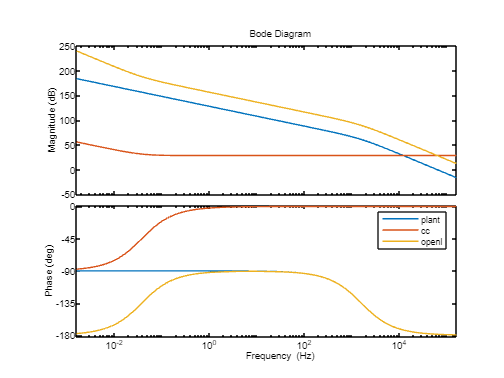

% 
% 
% options = bodeoptions;
% options.FreqUnits = 'Hz'; % or 'rad/second', 'rpm', etc.
% options.PhaseWrapping='on';
% 
% 
% bode(G_i,G_cc,G_openl,{10e-3,10e5}, options);
% legend('plant', 'cc','openl');

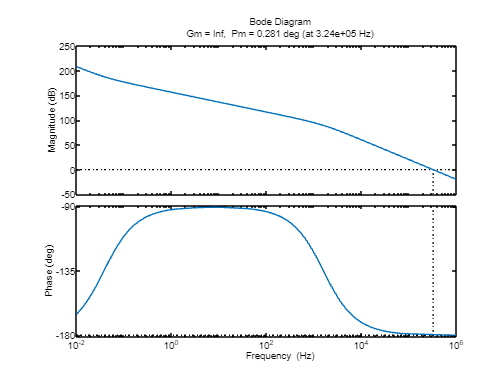

% % bode(G_cc/(1+G_cc),{10e-3,10e5})
% 
% options.XLim = [10e-3,10e5];
% % 
% margin(G_openl,options);

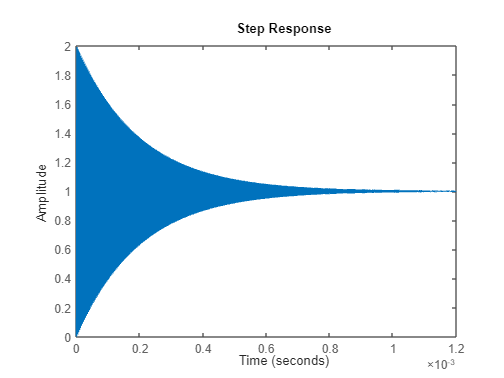

% % margin(G_cl)
% % step(G_cl)
% % pzmap(G_cl)
% step(G_openl/(1+G_openl))

% T_ers = 1/(2*pi*f_c)

T_ers = 1.5915e-04

% Gapprox = 1/(1+s*T_ers)

Gapprox =
 
         1
  ---------------
  0.0001592 s + 1
 
Continuous-time transfer function.
Model Properties


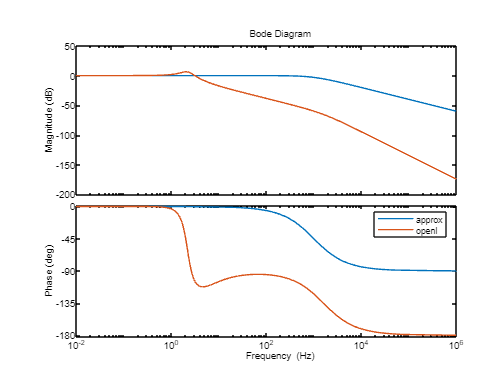

% bode(Gapprox,G_openl/(1+G_openl), options);
% legend('approx','openl');



% P0 = 1

P0 = 1

% p_1 = -1/T_ers

p_1 = -6.2832e+03

% z_1 = 3*1^2/(2*l_f*P0) % 3*1^2/(2*l_f*P0) %

z_1 = 56.6038

% UDC = 2%V_dc

UDC = 2

% UNd = 1%Vbase_lv

UNd = 1

% C = c_f

C = 0.0757

% L = l_f

L = 0.0265


% Gu=(3/2*UNd-s*L*P0/UNd)/(s*UDC*C);
% Gstr=Gapprox*Gu;


kpu= 0.03%3;

kpu = 0.0300

kiu = 0.3

kiu = 0.3000

Tnu=1;
% Gcu=kpu*(1+s*Tnu)/(s*Tnu);
% Gcu = kpu + kiu/s

Gcu =
 
  0.03 s + 0.3
  ------------
       s
 
Continuous-time transfer function.
Model Properties


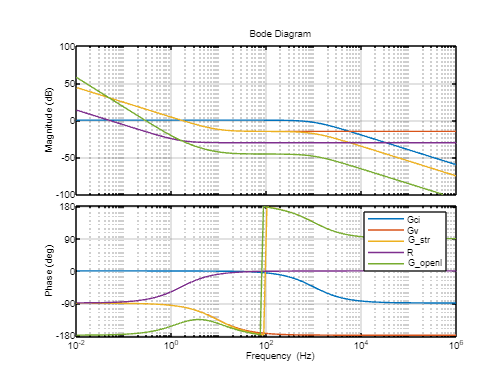

% 
% n0 = 1/(10^(-5/20));
% 
% a = 650;
% p = sqrt(a)*2*pi*50;
% N = n0*(s+p/a)/(s+p);
% 
% Golu=Gcu*Gstr;
% Gclu=Golu/(1+Golu); 

% figure(3);
% bode(Gapprox, Gu, Gstr,Gcu,Golu,options);
% legend('Gci', 'Gv', 'G_{str}','R','G_{openl}');
% grid on;

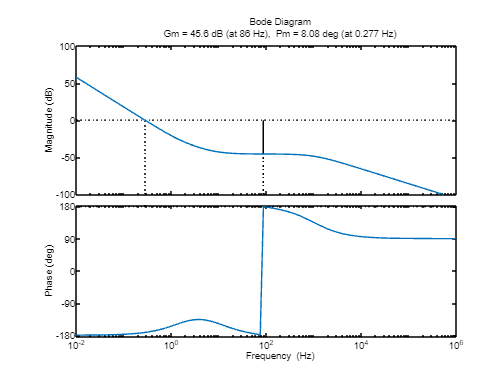

% figure(4);
% margin(Golu,options)

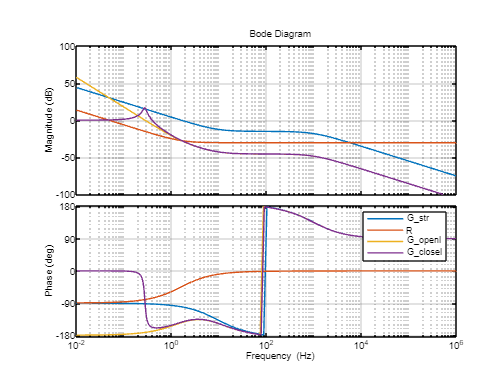

% figure(5);
% bode(Gstr,Gcu,Golu,Gclu,options);
% legend('G_{str}','R','G_{openl}','G_{closel}');
% grid on;


% a = 650
% asind((1-a*0.02)/(1+a*0.02))
% sqrt(Ki_vc*1/Tau_cc)
% ans*0.0757204
% G_dc = 0.005*Sbase1*(1+0.005*1/s)
% bode(G_dc,options)

% droop control

% (wmeas-wref)/(Pref-Pmeas) = kp_p

    % kp_p = (0.95-1)/(0.5-1)%0.05
    % 
    % % (vmeas-vref)/(Qref-Qmeas) = -kp_q
    % kp_q = (0.9-1)/(0-0.5)

## dc